%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 9维五阶段充电协议优化 - 单次实验HV收敛曲线绘图脚本
% 功能：仅加载第1次运行结果，快速验证HV收敛曲线
% 样式：和5次版本完全一致（配色/填充/字体）
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc;clear;close all;

% ========== 参考代码同款样式设置 ==========
% 颜色设置（和参考代码完全一致）
c = ['#A43546';'#1A5276';'#963CC2';'#4E9E35';'#AAAC4D';'#26F1F1'];
cc = [[220,144,156]/255;...
    [199,229,237]/255;[200,157,222]/255;...
    [233,255,233]/255;[252,255,228]/255;[216,255,255]/255];
facealpha = 0.3;  % 填充透明度
lw = 2;           % 线宽

% ========== 核心参数（仅改单次运行） ==========
result_dir = 'result_exp6';  % 结果文件夹
run_idx = 1;                % 仅加载第1次运行结果
iter_num = 180;              % 迭代次数（和主脚本一致）
REFER_UP = [8000,8,1.5];     % HV计算上参考点（和参考代码一致）
REFER_LOW = [2000,1,0.2];    % HV计算下参考点（和参考代码一致）

% ========== 初始化HV存储（单次运行无需矩阵） ==========
HVEEI = zeros(1, iter_num+1);  % TrOpt(EEI)的HV值（1×181）
HVPAR = zeros(1, iter_num+1);  % ParEGO的HV值（1×181）

% ========== 加载单次运行结果并计算HV ==========
fprintf('正在处理第 %d 次运行结果...\n', run_idx);

正在处理第 1 次运行结果...



% 1. 加载TrOpt(EEI)结果并计算HV
eei_file = fullfile(result_dir, sprintf('EEI_9d_run%d.mat', run_idx));
if exist(eei_file, 'file')
    load(eei_file);
    % 提取目标函数矩阵DB_EEI.y，计算HV
    HV1 = cal_hv(DB_EEI, REFER_UP, REFER_LOW);
    % 截取前181个点（20初始+180迭代）
    HVEEI(1,:) = HV1(1,1:iter_num+1);
else
    error(['TrOpt结果文件不存在：', eei_file]);
end

20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100
101
102
103
104
105
106
107
108
109
110
111
112
113
114
115
116
117
118
119
120
121
122
123
124
125
126
127
128
129
130
131
132
133
134
135
136
137
138
139
140
141
142
143
144
145
146
147
148
149
150
151
152
153
154
155
156
157
158
159
160
161
162
163
164
165
166
167
168
169
170
171
172
173
174
175
176
177
178
179
180
181
182
183
184
185
186
187
188
189
190
191
192
193
194
195
196
197
198
199
200



% 2. 加载ParEGO结果并计算HV
parego_file = fullfile(result_dir, sprintf('ParEGO_9d_run%d.mat', run_idx));
if exist(parego_file, 'file')
    load(parego_file);
    % 提取目标函数矩阵DB_ParEGO.y，计算HV
    HV2 = cal_hv(DB_ParEGO, REFER_UP, REFER_LOW);
    % 截取前181个点
    HVPAR(1,:) = HV2(1,1:iter_num+1);
else
    error(['ParEGO结果文件不存在：', parego_file]);
end

20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100
101
102
103
104
105
106
107
108
109
110
111
112
113
114
115
116
117
118
119
120
121
122
123
124
125
126
127
128
129
130
131
132
133
134
135
136
137
138
139
140
141
142
143
144
145
146
147
148
149
150
151
152
153
154
155
156
157
158
159
160
161
162
163
164
165
166
167
168
169
170
171
172
173
174
175
176
177
178
179
180
181
182
183
184
185
186
187
188
189
190
191
192
193
194
195
196
197
198
199
200


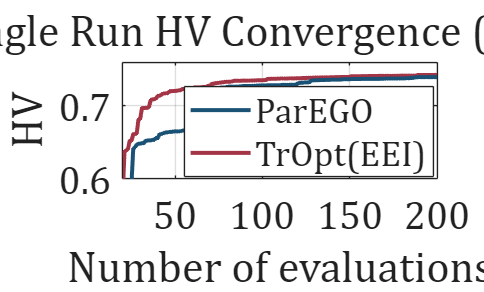


% ========== 单次运行无标准差（直接用原始值绘图） ==========
EEI_mean = HVEEI(1,:);    % 单次运行均值=原始值
EEI_std = zeros(size(EEI_mean));  % 单次运行无标准差（误差带为0）
PAR_mean = HVPAR(1,:);    % 单次运行均值=原始值
PAR_std = zeros(size(PAR_mean));  % 单次运行无标准差

% 保存HV统计结果（方便后续复用）
save(fullfile(result_dir, 'HV_single_run.mat'), 'EEI_mean','EEI_std','PAR_mean','PAR_std');

% ========== 绘制HV收敛曲线（和原样式完全一致） ==========
load(fullfile(result_dir, 'HV_single_run.mat'));
figure(1);
it = 20:1:200;  % 迭代轴（和参考代码一致：20~200）

% 1. 绘制TrOpt(EEI)曲线 + 误差带填充（无误差）
p1 = plot(it, EEI_mean, '-', 'LineWidth', lw, 'color', c(1,:), 'MarkerSize', 1);
hold on;
grid on;
y1 = EEI_mean + EEI_std;
y2 = EEI_mean - EEI_std;
h = fill([it,fliplr(it)], [y1,fliplr(y2)], cc(1,:));
set(h, 'edgealpha', 0, 'facealpha', facealpha);

% 2. 绘制ParEGO曲线 + 误差带填充（无误差）
p2 = plot(it, PAR_mean, '-', 'LineWidth', lw, 'color', c(2,:), 'MarkerSize', 1);
y1 = PAR_mean + PAR_std;
y2 = PAR_mean - PAR_std;
h = fill([it,fliplr(it)], [y1,fliplr(y2)], cc(2,:));
set(h, 'edgealpha', 0, 'facealpha', facealpha);

% ========== 图表样式设置（和参考代码完全一致） ==========
xlim([20, 200]);          % x轴范围
ylim([0.6, 0.76]);        % y轴范围（可根据单次结果调整）
legend([p2,p1], 'ParEGO', 'TrOpt(EEI)', 'Location', 'best');  % 图例
xlabel('Number of evaluations');  % x轴标签
ylabel('HV');                     % y轴标签
title(sprintf('Single Run HV Convergence (Run %d)', run_idx)); % 新增单次运行标题
set(gca, 'fontname', 'Cambria', 'fontsize', 20);  % 字体/字号

% ========== 保存图片 ==========
fig_path = fullfile(result_dir, sprintf('HV_convergence_single_run_%d.png', run_idx));
saveas(gcf, fig_path);

fprintf('\n✅ 单次运行HV收敛曲线已保存到：%s\n', fig_path);


✅ 单次运行HV收敛曲线已保存到：result_exp6\HV_convergence_single_run_1.png
